clc;clear;
nMems = 3;
N = 400;
simN = 7;
dirs = dir(fullfile("Data", "N"+num2str(N), num2str(nMems) + "memories"));
file = fullfile(dirs(simN).folder, dirs(simN).name, "patch" + num2str(nMems) + ".mat");
load(file, 'obj'); net = obj; clear obj; net.RecordingDirectory = string(fullfile(dirs(simN).folder, dirs(simN).name));
data = net.getData();
whos

  Name        Size                Bytes  Class                Attributes

  N           1x1                     8  double                         
  data        1x1             808479039  struct                         
  dirs       15x1                 15726  struct                         
  file        1x1                   454  string                         
  nMems       1x1                     8  double                         
  net         1x1                     8  IzhikevichNetwork              
  simN        1x1                     8  double                         



net.baseFolder = fullfile("Data", "N" + num2str(N), num2str(nMems) + "memories");
[order1, order2, spike_counts, delays] = computeOrders(net, 100);

% === PCA on Delays ===
[coeff, score, latent, tsquared, explained, mu]  = pca(spike_counts(:, 1:320));  % score is [3000 x N_PC]

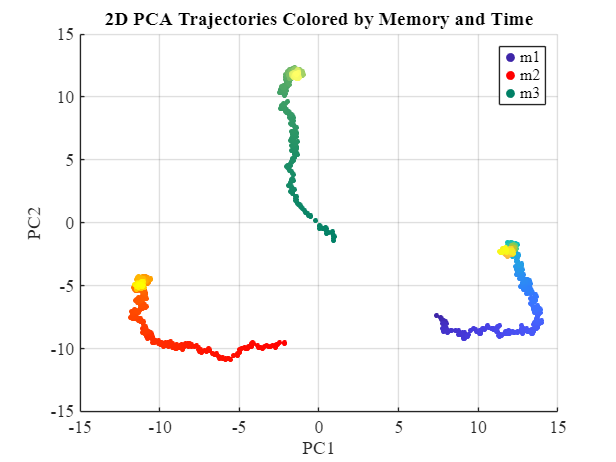


% === Parameters ===
T = 1000;                      % Trials per memory
labels = repmat(1:3, 1, T)';   % Memory label
time   = repmat(1:T, 3, 1);    % Trial index
time   = time(:);

% === Base Colormaps for Each Memory ===
cmaps = {
    parula(T);    % Memory 1 → blue-ish
    autumn(T);    % Memory 2 → red-orange
    summer(T);    % Memory 3 → green-yellow
};

% === Plot Setup ===
figure('Color', 'w'); hold on;
xlabel('PC1'); ylabel('PC2');
title('2D PCA Trajectories Colored by Memory and Time');
set(gca, 'FontSize', 12); grid on;

legend_entries = [];

% === Plot Each Memory Trajectory ===
for mem = 1:3
    idx = labels == mem;
    pc2d = score(idx, :);   % PC1 and PC2
    t = time(idx);            % Trial 1:T
    c = cmaps{mem};           % Get colormap
    scatter(pc2d(:,2), pc2d(:, 3), 12, c, 'filled');
    
    % Add fake point for legend
    h(mem) = scatter(NaN, NaN, 30, c(1,:), 'filled');
end

legend(h, {'m1', 'm2', 'm3'}, 'Location', 'northeast');

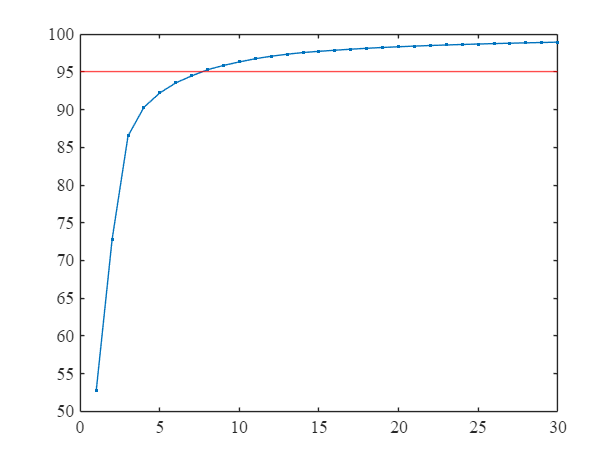

figure; plot(cumsum(explained), '.-'); xlim([0 30]); yline(95, 'r-'); 

clc;clear;
nMems = 3;
alpha = 90;
N = 400;

dirs = dir(fullfile("Data", "N"+num2str(N), num2str(nMems) + "memories"));
file = fullfile(dirs(3).folder, dirs(3).name, "recallsResponses", "alpha_" + num2str(alpha)+ ".mat");
load(file)
whos

  Name                      Size               Bytes  Class     Attributes

  N                         1x1                    8  double              
  X_responseActivity      400x400            1280000  double              
  Y_memoryClass           400x1                 3200  double              
  alpha                     1x1                    8  double              
  dirs                     15x1                15726  struct              
  file                      1x1                  486  string              
  nMems                     1x1                    8  double              



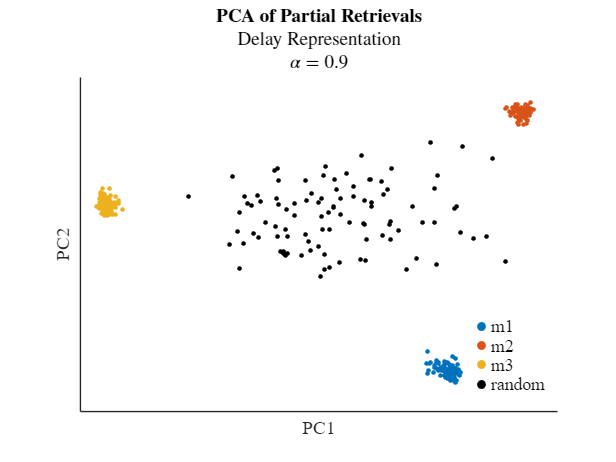



X_responseActivity(isnan(X_responseActivity)) = 0;
[coeff, score, latent, tsquared, explained] = pca(X_responseActivity);

% Get unique memory classes
memoryLabels = unique(Y_memoryClass);

% Generate colormap
cmap = lines(nMems);

% Plot with loop
figure; hold on;
for i = 1:nMems
    idx = Y_memoryClass == i;
    % scatter3(score(idx, 1), score(idx, 2), score(idx, 3), 10, cmap(i, :), 'filled', ...
    %     'DisplayName', "m" + num2str(memoryLabels(i)));
    scatter(score(idx, 1), score(idx, 2), 10, cmap(i, :), 'filled', ...
    'DisplayName', "m" + num2str(memoryLabels(i)));
end

idx = Y_memoryClass == nMems+1;
% scatter3(score(idx, 1), score(idx, 2), score(idx, 3), 10, 'k', 'filled', ...
%     'DisplayName', "random");
scatter(score(idx, 1), score(idx, 2), 10, 'k', 'filled', ...
    'DisplayName', "random");

xlabel('PC1'); ylabel('PC2'); zlabel('PC3');
title({'\textbf{PCA of Partial Retrievals}', 'Delay Representation', "$\alpha=$" + num2str(0.01*alpha)}, 'Interpreter', 'latex','FontName', 'Times New Roman', 'FontSize', 12);
legend('Location', 'best', 'FontName', 'Times New Roman', 'FontSize', 12, 'Box','off');

% view(3); zticks([]);
xticks([]); yticks([]); 
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12)
print(fullfile("Results", "PCAOfRetrievals", sprintf("PCA_AlternatingLearningAlpha%d.png", alpha)), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "PCAOfRetrievals", sprintf("PCA_AlternatingLearningAlpha%d.pdf", alpha)), 'ContentType', 'vector');

function [check_flag_save2, check_flag_save, total_spike_count, time_delays] = computeOrders(net, interval)
    % Computing the order vectors from patch.mat files for computation speed reasons:)

    if nargin < 2
        interval = 100;
    end
    off_set_time = 0;
    
    check_flag_save2 = zeros(round(net.t/interval), net.N);
    check_flag_save = zeros(round(net.t/interval), net.N);
    total_spike_count = zeros(round(net.t/interval), net.N);
    time_delays = zeros(round(net.t/interval), net.N);
    % ex_neurons_engagement_count = zeros(1, round(net.t/interval));
    % inh_neurons_engagement_count = zeros(1, round(net.t/interval));
    
    f = waitbar(0, "Computing First to Spike Orders ...");
    trial_counter = 0;
    time_keeper = 0;
    for patch_num = 1:net.PatchNumber-1
        patch_address = net.RecordingDirectory + filesep + "Patch" + num2str(patch_num) + ".mat";
        pathParts = strsplit(patch_address, {'\', '/'});
        patch_address = fullfile(pathParts{:});
    
        variable_name = "data" + num2str(patch_num);
        s = load(patch_address);
        data = getfield(s, variable_name);
        temp_net = getfield(s, 'obj');
        firings = transpose(data.firings);
        firings(:, 1) = firings(:, 1) - time_keeper;
        
        for trial_number = 1:round((temp_net.t-time_keeper)/interval)
            % Computing the orders
            
            start_time = (firings(:, 1) > (trial_number-1) * interval + off_set_time);
            end_time = (firings(:, 1) <= trial_number * interval + off_set_time);
            indices = start_time & end_time;
            spike_times = firings(indices, 1) - (trial_number-1) * interval;
            neuron_indices = firings(indices, 2);    
        
            [order, delay] = TimeToFirstSpikeSort(spike_times, neuron_indices, true, net.N, net.Ne);
            [order2, ~] = TimeToFirstSpikeSort(spike_times, neuron_indices, false, net.N, net.Ne);
            trial_counter = trial_counter + 1;
            check_flag_save(trial_counter, :) = order;
            check_flag_save2(trial_counter, :) = order2;
            [GC,GR] = groupcounts(neuron_indices); total_spike_count(trial_counter, GR) =  GC;
            time_delays(trial_counter, :) = delay;
            % ex_neurons_engagement_count(trial_counter) = sum(unique(neuron_indices)<=net.Ne);
            % inh_neurons_engagement_count(trial_counter) = sum(unique(neuron_indices)>net.Ne);
    
            waitbar(patch_num/(net.PatchNumber-1), f, sprintf("Computing First to Spike Orders ... \n trial %d, patch %d/%d", trial_counter, patch_num, net.PatchNumber-1))
        end
    
        time_keeper = temp_net.t;
    end
    
    close(f)
end

function [order, time_delay] = TimeToFirstSpikeSort(spike_times, neuron_indices, separated, N, Ne)
    % TimeToFirstSpikeSort Sorting neurons based on first time to spike.
    %
    % Syntax:
    %   order = TimeToFirstSpikeSort(spike_times, neuron_indices)
    %
    % Description:
    %   A detailed description of the function, explaining its purpose and
    %   how it works.
    %
    % Input Arguments:
    %   spike_times - an array of spike timings.
    %   neuron_indices - an array of neuron indices of spikes.
    %   separated - if order excitatory and inhibitory spikes separately or
    %   together
    %
    % Output Arguments:
    %   order - ordered indices of neurons by who spiked earlier.
    
   
    order = zeros(1, N); % a vector that labels cells by spike order
    time_delay = zeros(1, N); % time of first spike of each neuron
    % neuron_sorted_indices = zeros(size(spike_times, 1), 1); % sorted neuron indices signal
    
    if separated 
        counter_ex = 1;
        counter_inh = Ne + 1;
        
        for i = 1:length(spike_times)
            if neuron_indices(i) <= Ne
                if order(neuron_indices(i)) == 0 % First excitatory spikes
                    % neuron_sorted_indices(i) = counter_ex;
                    order(neuron_indices(i)) = counter_ex;
                    time_delay(neuron_indices(i)) = spike_times(i);
                    counter_ex = counter_ex + 1;
                else % Repeated excitatory spikes
                    % neuron_sorted_indices(i) = order(neuron_indices(i));
                end
            else
                if order(neuron_indices(i)) == 0 % First Inhibitory spikes
                    % neuron_sorted_indices(i) = counter_inh;
                    order(neuron_indices(i)) = counter_inh;
                    time_delay(neuron_indices(i)) = spike_times(i);
                    counter_inh = counter_inh + 1;
                else % Repeated Inhibitory spikes
                    % neuron_sorted_indices(i) = order(neuron_indices(i));
                end
            end  
        end
    end

    if ~separated
        counter = 1; 
        for i = 1:length(spike_times)
            cell = neuron_indices(i);
            if order(cell) == 0 % First spike
                % neuron_sorted_indices(i) = counter;
                order(cell) = counter;
                time_delay(cell) = spike_times(i);
                counter = counter + 1;
            else % Repeated spike
                % neuron_sorted_indices(i) = order(cell);
            end
        end
    end

end